%-------------------------------%
%   Challenge Session No. 4
%-------------------------------%
%Rodrigo Gamboa & Francisco Montes | May 2024


%------------Part 3---------------% 
%FUNCTION DEFINITION | DECLARATION
%---------------------------------%

%Change the name of this tab to the name of the referred or associated
%function (the one that got you here in the first place). 
%e.g. If the function called in the main code is f_meg(x,y), this
%tab should be called then f_meg.m, for Matlab to locate it. Be sure to 
%save it in the same directory as your main code. 

%Definition or declaration of a function called
%[x,y,phiB2,Bz]=B_due_M(zm(cc+1),mag,Rring);
%that takes (input) _____, ____ and _____; and returns (output)
%_____, ______, ______ and _____.

%Declare the function here, start by checking reserved word/code for
%MatLab, to declare a function.


%[Reserved word for definig a function] <function call>
function [x,y,phiB,Bz]=B_due_M(z,mag,Rring)

    mo=4*pi*1e-7;            %Just uncomment.
    ds=0.005;                %Uncomment and continue ahead and then go back here to comment
                             %on the meaning of this variable.
    
    x = -Rring:ds:Rring;        %Declare a x array, extending from -Rring to Rring in steps of ds.   
    y = x;                      %Declare a y array, extending from -Rring to Rring in steps of ds.
    Lx = length(x);             %Define an array called Lx such that it has the
                                %same length than the array x.
    
    Ly = length(y);             %Define an array called Ly such that it has the
                                %same length than the array y.
    
    Bz = zeros(Lx, Ly);         %Define a 2D matrix, or array called Bz, such that
                                %it has entries from 1 to Lx and 1 to Ly, for the ith 
                                %and jth components, respectively, and initialize all 
                                %of them to zero.
    
    
    phiB = 0;                   %Introduce a variable called phiB, and set it
                                %equal to zero.
    
    
    for i=1:Lx                  %Start a for loop using an "i" counter going from 1 to Lx.
        for j=1:Ly              %Start a for loop using a "j" counter going from 1 to Ly.
    
            r=sqrt(x(i)^2+y(j)^2);        %Uncomment and comment what exactly is this?
                                          %MAKE A DRAWING!!!
    
            if r<Rring                    %Why this? Comment and think!
    
                %Bz(i,j) = WRITE HERE THE EQUATION FOR THE FIELD FROM CANVAS
                Bz(i, j) = (mo/(4*pi)) * ((3*z*(mag*z)-mag*(x(i)^2 + y(j)^2 + z^2))/(x(i)^2 + y(j)^2 + z^2 + (ds^2))^(-5/2));
                
                

                % "STAGE 3: Calculation of induced fem by a magnet (dipole) free falling through a coil"
    
                phiB=phiB+ds^2*Bz(i, j);   %Following intructions in CANVAS, write here the
                          %value for the B-Field Flux!
            end
             %Close (end) the "if".   
        %Close the for with the "j" counter.
        end
    %Close the for with the "i" counter.
    end
end

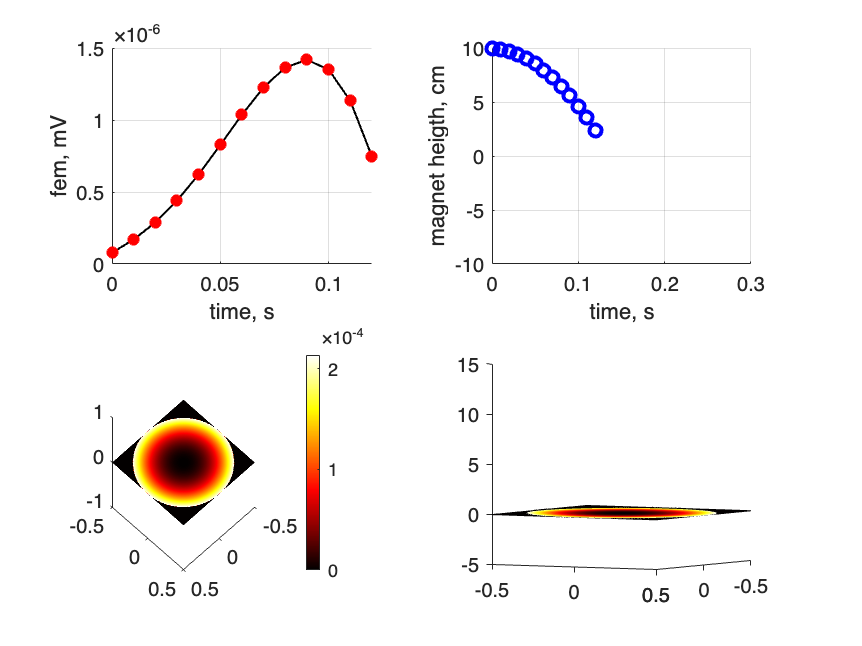

%-------------------------------%
%    Challenge Session No. 4
%-------------------------------%
%Rodrigo Gamboa & Francisco Montes | May 2024


%%%%%%%%%%%%%%%%%%%%%%%%%%
%IMPORTANT FINAL COMMENTS%
%%%%%%%%%%%%%%%%%%%%%%%%%%

% This is your minimum SECOND (and final) DELIVERABLE. The maximum (which will warranty a 
% direct 100 grade in the deliverable), and a VERY well-received thing to have for your  
% ORAL EXAM, is the integration of this code to the previous one (i.e., the one for the 
% first deliverable). In fewer words, an animation of a magnet falling through the axis  
% of a coil, experiencing magnetic braking due to the induced current by
% by the falling magnet.


%%%%%%%%%%%%%%%%
%TODAY´s SESSION
%%%%%%%%%%%%%%%%

%The objective for this session is to model/find the induced voltage 
%(potential difference, or electromotive force, namely fem), generated by 
%a magnet free falling from a zo height, along the axis of a conductor
%ring or loop (with radious Rring). IMPORTANT: The loop conductor located at 
%z=0 no longer has a steady electric current, as before. The associated 
%current will be generated by the associated induced fem.

%Assume a magnet with a magnetic dipole moment "mag".
%Assume the magnet has a small radius, 10 times smaller than the ring.
%Model the magnet as an electrical current ring of r=Rring/10
%Calculate the z component of the magnetic field produced by that ring. 


%START% PART I

clear             %Add comment, what are these for?
clc               %Add comment
clf               %Add comment

mag = 500;        %Define a "mag" variable to define the magnetic moment
                  %of the falling magnet, and set it equal to 500.

Rring = 0.5;      %Define a "Rring" variable to define the ring
                  %radius in m. Set it equal to 0.5.

zo = 0.1;               %Define initial position of magnet (zo). Set it equal to 0.1.
zring = 0;              %Define ring position (use "zring" variable). Set it equal to 0.
dt = 0.01;              %Define time step ("dt"). Set it to 0.01.
t = []; t(1) = 0;       %Define a time vector, and initialize to zero its first
                        %entry.

zm = []; zm(1) = zo;    %Define a Z-position vector (zm), and initialize to "zo" its first
                        %entry.

cc = 1;                 %Define a "cc" counter; set it equal to 1.
vz = []; vz(1) = 0;     %Define a vz vector; initialize its first entry to zero.

       %Call for figure(1).
%-------------------------------%
%   Challenge Session No. 4
%-------------------------------%
%Rodrigo Gamboa & Francisco Montes | May 2024



%--------Part 2---------% [after %Call for figure(1).]

%Use [open and close] a while loop, using the zm variable vector, such that
%you can warranty that all z values for the magnet while falling from zo to
%JUST BEFORE passing through the coil are covered (i.e., from zm = zo to 
%zm = 0.0162).


%Inside the while loop, use the following (uncomment), and
%explain what it does or will do.

while zm(cc) > (0.0162)
pause(0.005);     %Comment
clf;              %Comment
    
    [x,y,phiB1,Bz1]=B_due_M(zm(cc),mag,Rring);

    %What is this? Explain in full detail, take your time!
    %___________________________________________________________
    %___________________________________________________________
    %___________________________________________________________
    %___________________________________________________________

%Using kinematics, the same as in last week's code actually, write an
%expression for the zm position of the magnet, while free falling.

    zm(cc + 1) = zm(cc) + vz(cc)*dt - 9.81*dt^2;

%Using kinematics, the same as in last week's code actually, write an
%expression for the vz position of the magnet, while free falling.

    vz(cc + 1) = vz(cc) - 9.81*dt;

    [x,y,phiB2,Bz2]=B_due_M(zm(cc+1),mag,Rring);

    %What is this? Explain in full detail, take your time!
    %___________________________________________________________
    %___________________________________________________________
    %___________________________________________________________
    %___________________________________________________________

%-------------------------------%
%   Challenge Session No. 4
%-------------------------------%
%Rodrigo Gamboa & Francisco Montes | May 2024


%--------Part 4---------% fem CALCULATION | DECLARATION
    
    %-- After the second instance call for 
    %[x,y,phiB2,Bz]=B_due_M(zm(cc+1),mag,Rring);
     
  
    %Taking into account that the B_due_M function has been called 
    %twice (why)? Calculate a vector function of fem(cc) equal to the
    %"rate change or difference of the magnetic flux, with respect to
    % time", associated with the area of the ring (coil or wire loop).

    fem(cc)=(phiB2 - phiB1)/dt;

    %Uncomment all of the following, and explain in detals what each line 
    %is doing.

    subplot(2,2,1)
    hold on
    grid on
    xlabel 'time, s'
    ylabel 'fem, mV'
    plot(t(1:cc),100*fem(1:cc),'-k','LineWidth',1)
    plot(t(1:cc),100*fem(1:cc),'*r','LineWidth',2)
    

    subplot(2,2,2)
    hold on
    axis([0 0.3 -10 10])
    grid on
    xlabel 'time, s'
    ylabel 'magnet heigth, cm'
    plot(t(1:cc),100*zm(1:cc),'ob','LineWidth',2)    

    subplot(2,2,3)
    hold on
    pcolor(x,y,zm(cc)/abs(zm(cc))*abs(abs(0.005^2*Bz1)).^(1/3)); shading interp; colormap hot; colorbar
    view(-45,-45)

    subplot(2,2,4)
    
    hold on
    mesh(x,y,zm(cc)/abs(zm(cc))*abs(abs(10^2*Bz1)).^(1/3)); 
    view(-30,-3)
    axis([-Rring Rring -Rring Rring -5 15])
    
    cc=cc+1;
    t(cc)=t(cc-1)+dt;
   
% close the while loop
end

%END OF CODE !!!%